# 요약 및 예제

## 1. Reference code에 포함된 내용

- spike detection algorithm

- cluster average waveform with confidence band

- raster plot

- colored raster plot

- PCA

- kmeans

- calculation of discrete derivative(dV/dt)

- ISI(interspike interval) plot

## 2. Reference code에 포함되지 않아서 제가 추가한 내용

- Baw data file을 불러와서 정리하여 array로 바꾸는 함수

- Bandpass filter 적용을 위한 resampling과 [300hz, 3000hz] bandpass filter 적용

- Bandpass filter 적용을 통한 theta wave 획득 및 Hilbert transform을 통한 theta phase 계산

- circstat 패키지를 이용한 theta phase 분포 plot 및 phase lock test

- phase-space plot

- FWHm(full width half minimum) 계산 및  month 단위로 합쳐서 bar plot으로 비교

## 3. Reference code를 변경한 내용

- 기존 코드는 sampling frequency 30000에 맞춰서 모든 코드가 구성되어 있어서, sampling frequency가 다른 데이터에 적용하면 제대로 작동하지 않았음(ms <-> timestamp 간 변환 관련) -> 데이터의 sampling frequency를 자동으로 계산하고, 계산한 값에 맞추어 다른 알고리즘이 동작하도록 수정

- PCA 수행 시 standardization 시행

- k-means 수행 시 seed number 사용

- 여러 채널의 데이터를 효율적으로 관리하고 관련 데이터와 변수를 한 곳에 모아 놓기 위해 class 제작: channel이라는 object에 데이터 파일 하나의 raw data, filtered data, PCA 및 kmeans 결과 등이 저장됨

- plotting도 object를 통해 수행하도록 함:

- 간단한 plotting의 경우 object에서 얻은 데이터를 matlab 함수를 사용해 직접 plotting

- 복잡한 plottin의 경우 object에 내장시킨 metho를 통해 plotting하도록 설계

## 4. 파일 목록

- CyborgBrainOrg.m : 원본 reference code를 주어진 데이터에서 돌아가도록 수정완료한 파일

- channel.m : 데이터 및 변수의 효율적 관리를 위해 만든 channel class 정의 파일. CyboarBrainOrg.m의 내용이 리팩토링되어 들어가 있음

- longtermAnalyzer.m: 여러 organoid, channel, month 데이터를 통합 관리하고 month 별로 묶어 plotting하기 위해 만든 longtermAnalyzer class 정의 파일

## Figure 2.f.

                        %organoid, channel, month 
o1_ch8_m1 = channel("rawData.csv", 1, 8, 1);
o1_ch8_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz

                        %thres, pre_time, post_time
o1_ch8_m1.detectSpikes(5,2,2);

o1_ch8_m1.getPCScores();
                           %clusternum, seednum
o1_ch8_m1.getKmeansClusters(3,1);

o1_ch8_m1.getThetas();

raw trace, filtered trace, raster polot

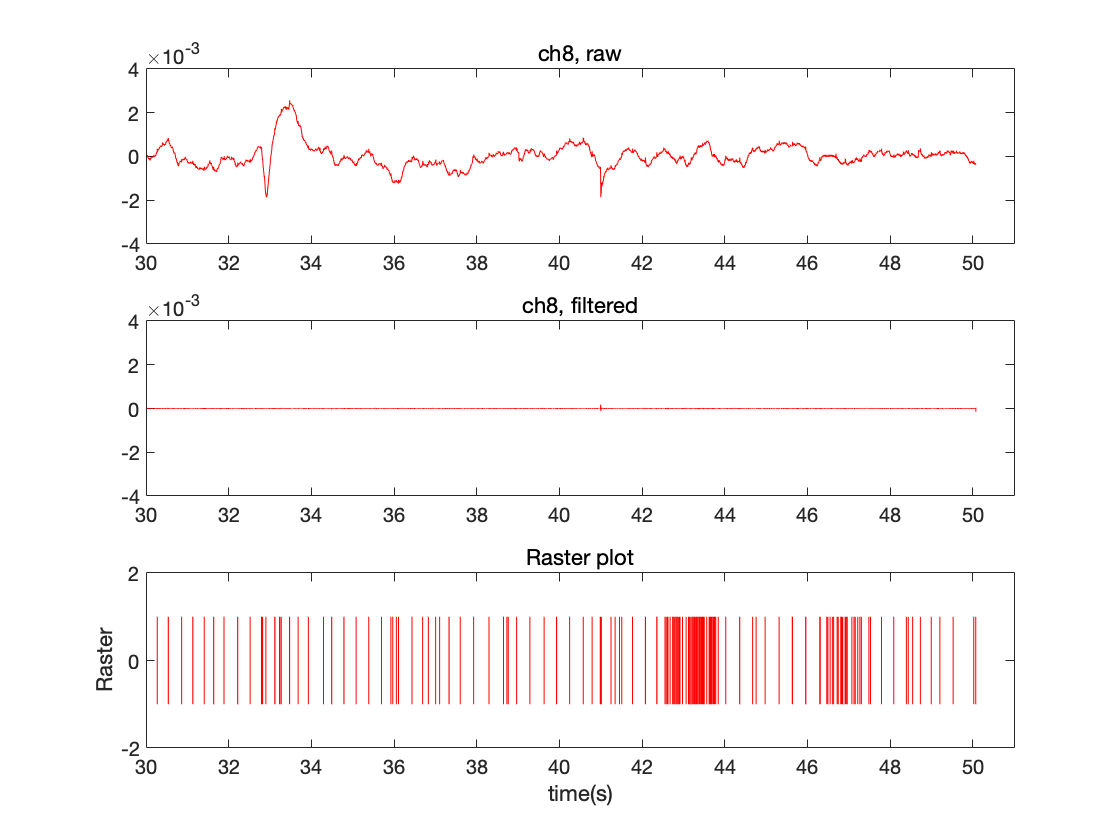

figure
subplot(3,1,1)
pRaw = plot(o1_ch8_m1.t, o1_ch8_m1.raw);
pRaw.Color = 'red';
title('ch8, raw');
ylim([-4,4]*1e-3);%ylim 조절 가능
xlim([30,51]); %xlim 조절 가능

subplot(3,1,2)
pFiltered = plot(o1_ch8_m1.t, o1_ch8_m1.filtered);
pFiltered.Color = 'red';
title('ch8, filtered');
ylim([-4,4]*1e-3);%ylim 조절 가능
xlim([30,51]); %xlim 조절 가능

subplot(3,1,3)
o1_ch8_m1.drawRaster('red');
xlim([30,51]); %xlim 조절 가능

## Figure 2.g.

zoom-in window on the same spike(20th, for example) before and after filtering

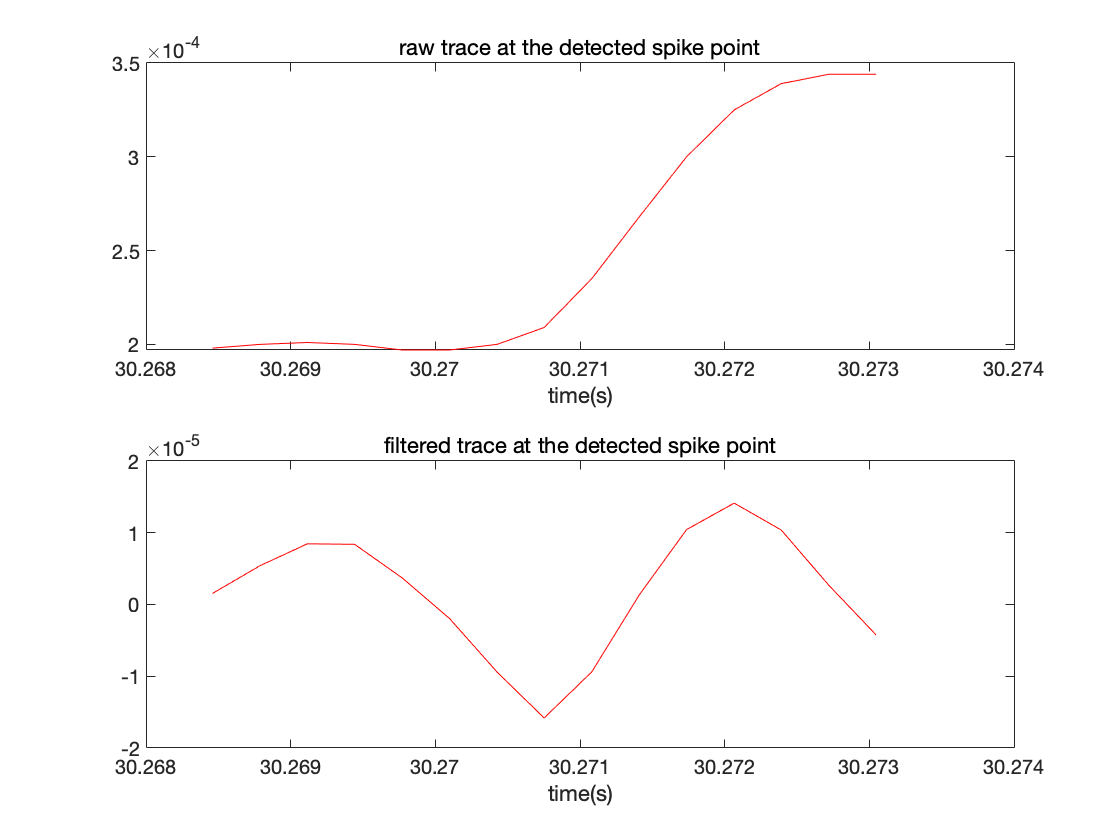

spikeTimestamps = o1_ch8_m1.spikeTimestamps;
ts = spikeTimestamps(1); %location of the 20th spike
tsInterval = ts + (-o1_ch8_m1.timestampsPrePeak : o1_ch8_m1.timestampsPostPeak);

figure
subplot(2,1,1)
pRaw = plot(o1_ch8_m1.t(tsInterval), o1_ch8_m1.raw(tsInterval));
pRaw.Color = 'red';
title('raw trace at the detected spike point');
xlabel('time(s)');

subplot(2,1,2)
pFiltered = plot(o1_ch8_m1.t(tsInterval), o1_ch8_m1.filtered(tsInterval));
pFiltered.Color = 'red';
title('filtered trace at the detected spike point');
xlabel('time(s)');

## Figure 2.h

PCA and average waveform for each cluster

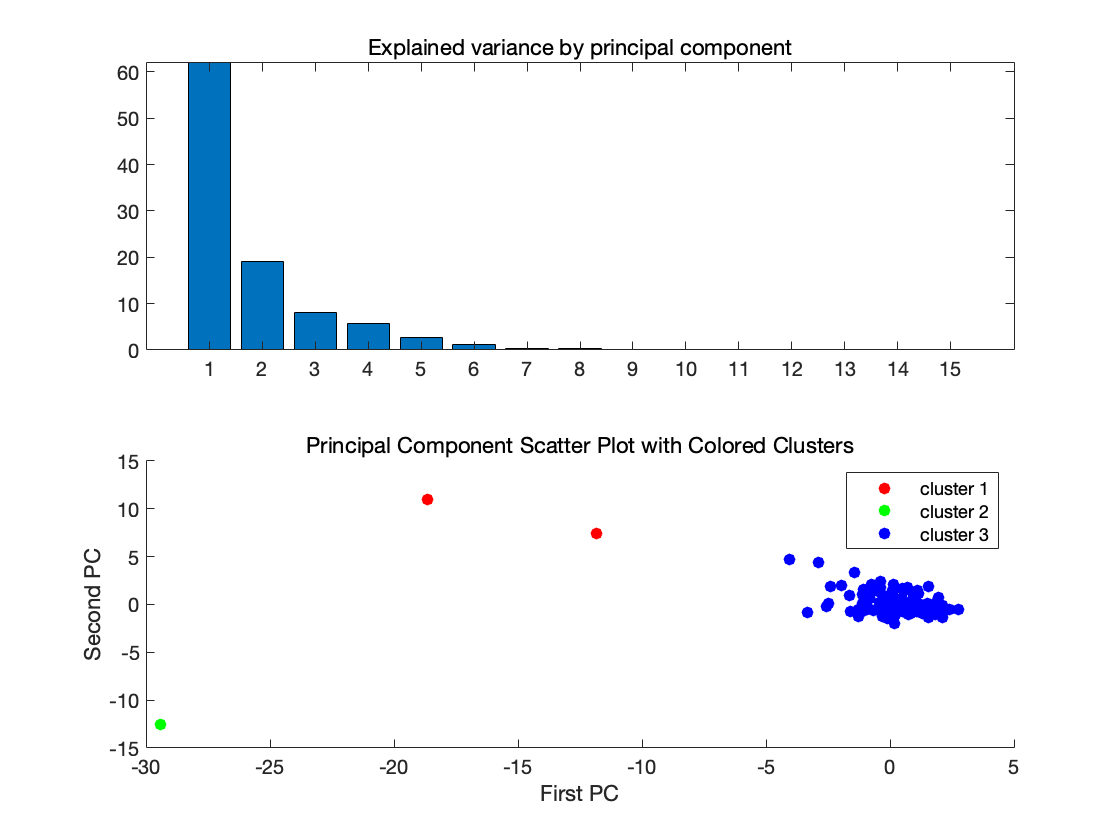

figure

o1_ch8_m1.drawPCA()

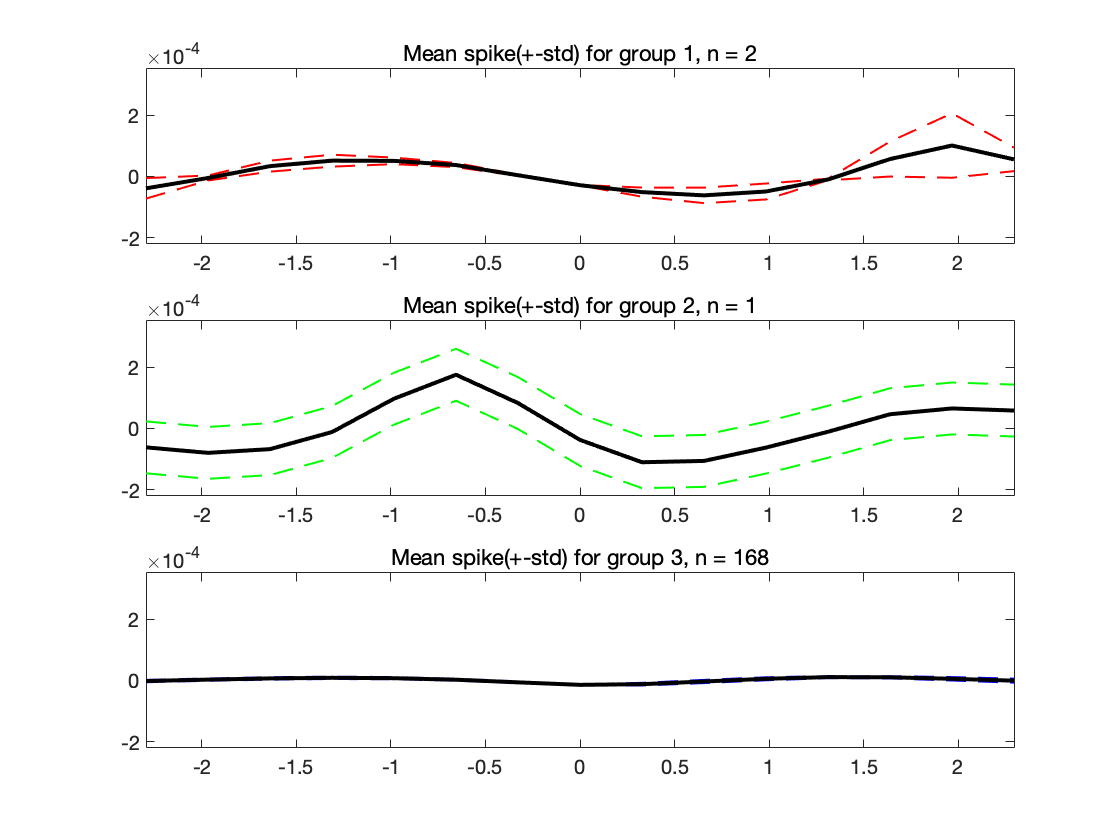


figure
o1_ch8_m1.drawClusterMeanSpikes();

## Figure 2.i

colored raster plot. 클러스터 3개일 때는 파란색이 압도적으로 많아 구분이 잘 되지 않으므로, 일시적으로 클러스터 5개로 수정

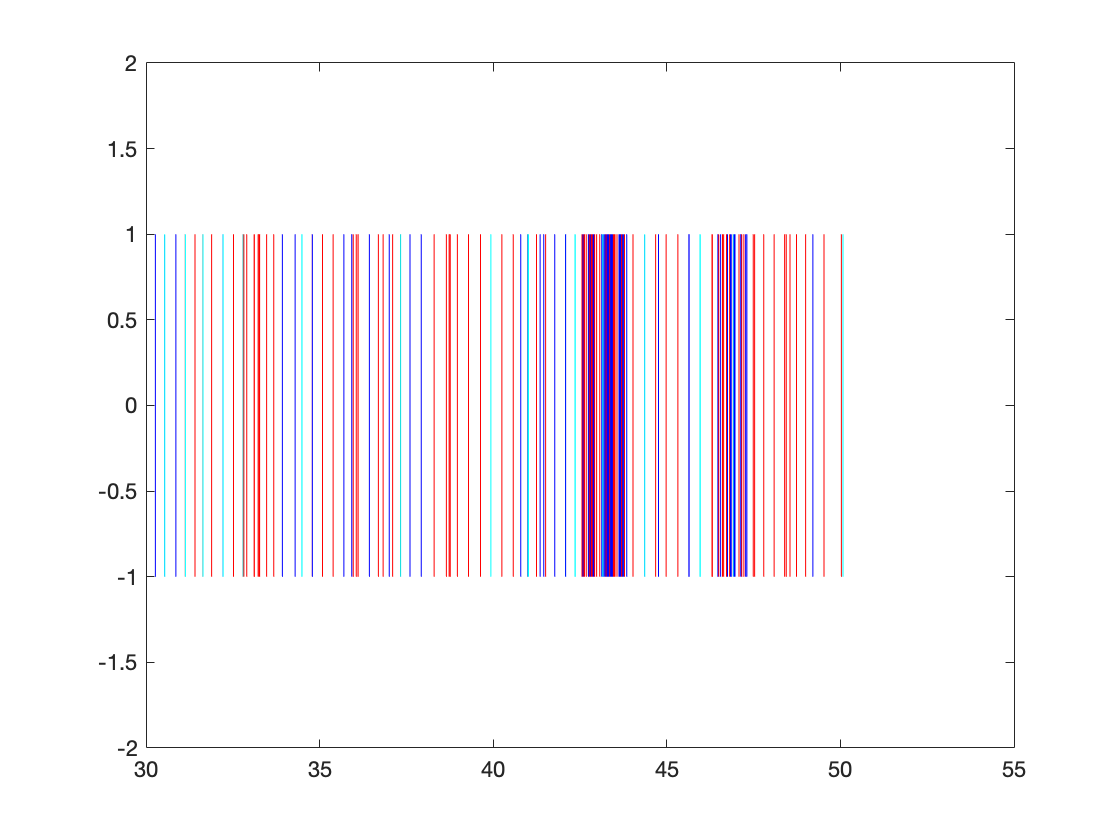

o1_ch8_m1.getKmeansClusters(5,1);
figure
o1_ch8_m1.drawColoredRaster();

o1_ch8_m1.getKmeansClusters(3,1);


## Figure 2.j.

interspike intervals histogram

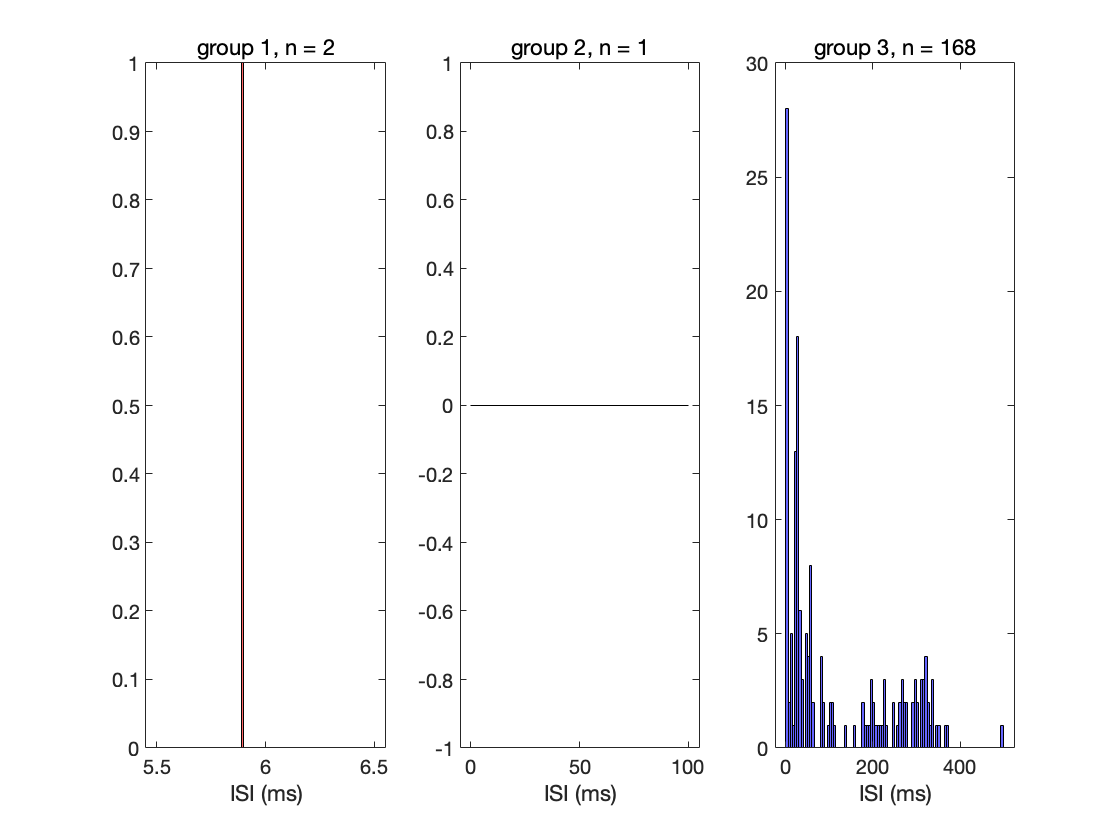

figure
o1_ch8_m1.drawISI();

## Figure 2.k

theta waves and theta phase

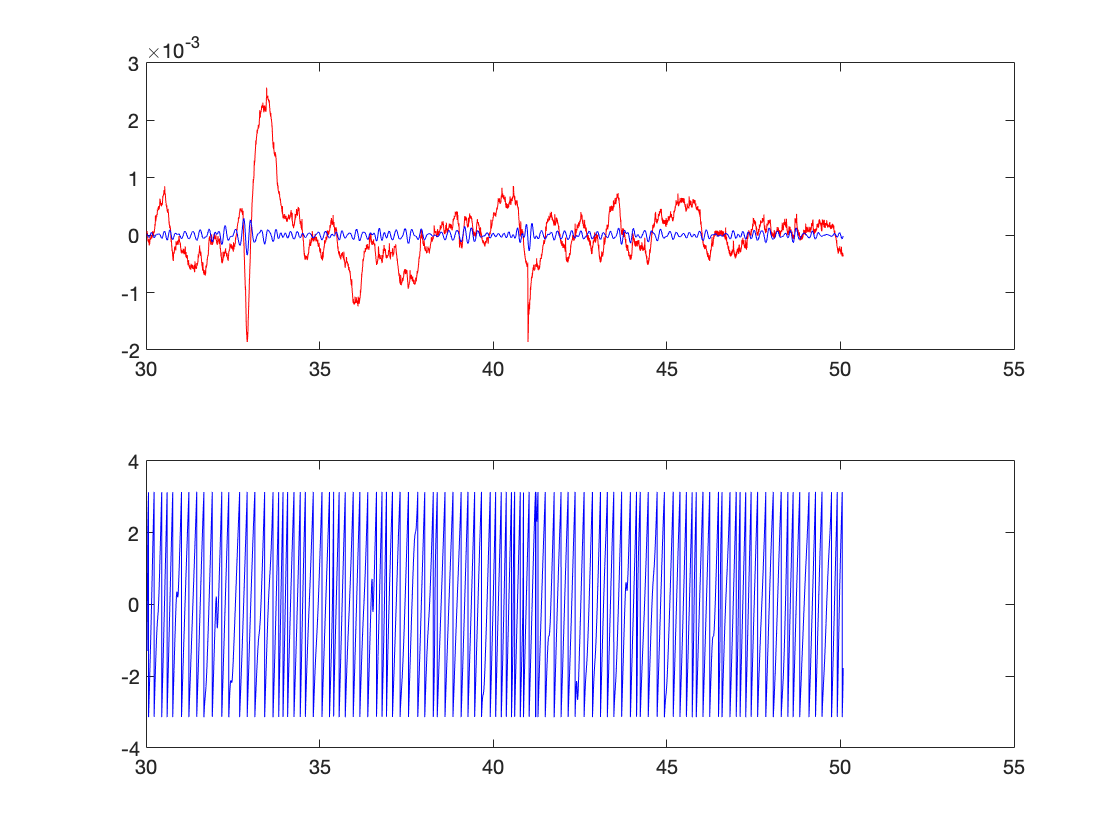

figure
subplot(2,1,1)
p_raw = plot(o1_ch8_m1.t, o1_ch8_m1.raw);
p_raw.Color = 'red';

hold on;

p_thetaWaves = plot(o1_ch8_m1.t, o1_ch8_m1.thetaWaves);
p_thetaWaves.Color = 'blue';

hold off;

subplot(2,1,2)
p_thetaPhases = plot(o1_ch8_m1.t, o1_ch8_m1.thetaPhases);
p_thetaPhases.Color = 'blue';

## Figure 2.m

Circular distribution of theta angles

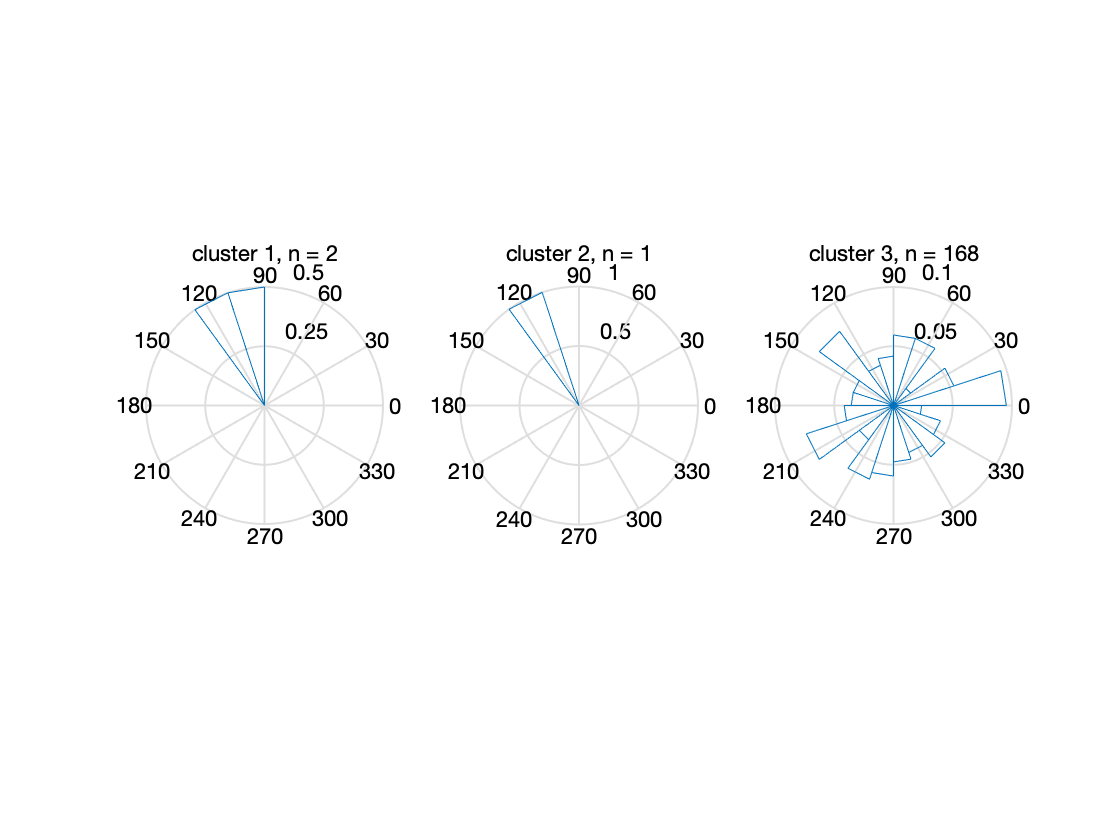

figure
o1_ch8_m1.drawCircularTheta();

## Figure 2.n. 

distrubution of theta angles

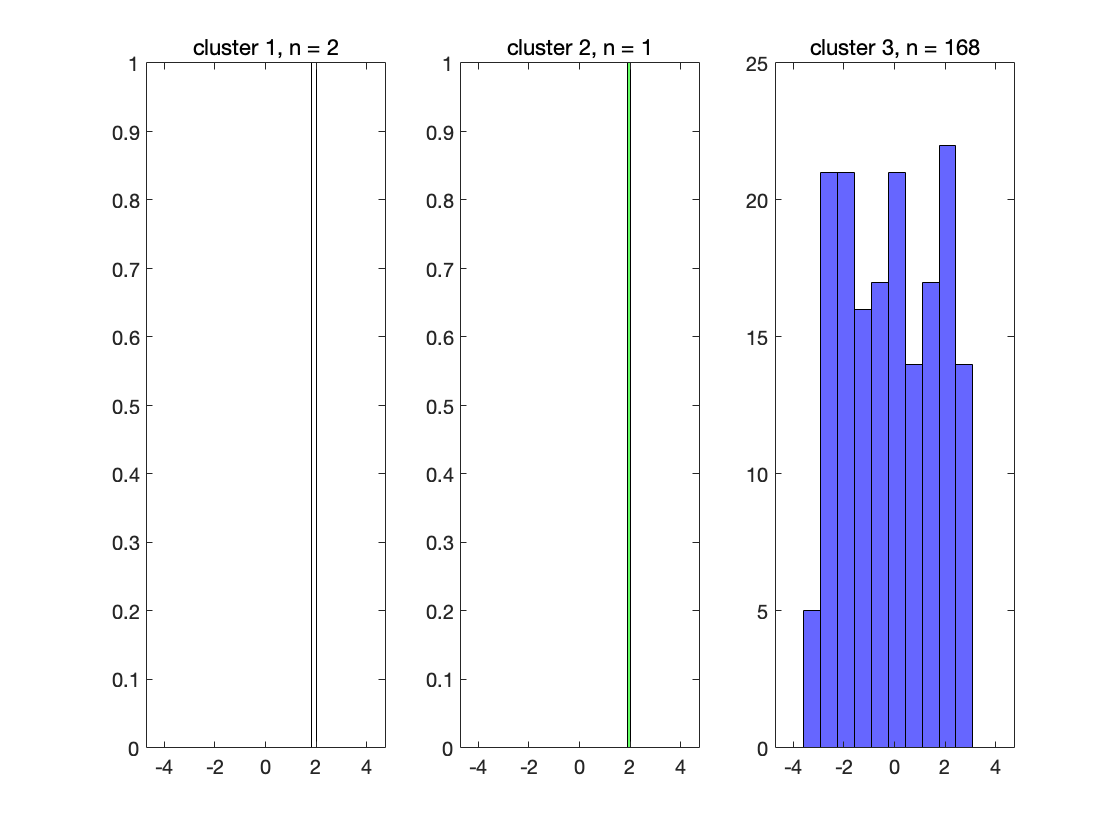

figure
o1_ch8_m1.drawThetaHist();

testing the non-uniformty of theta phase distribution using Rayleigh criterion to detect phase-locking.

We considered that phase-locking to theta waves happens for P-values below 0.05.

o1_ch8_m1.uniformTest()

pvals =     0.1397
    0.4658
    0.9354


## Figure 2.o-q

월별 비교

%organ, ch, month
o1_ch1_m1 = channel("rawData.csv", 1, 1, 1);
o1_ch2_m1 = channel("rawData.csv", 1, 2, 1);
o2_ch1_m1 = channel("rawData.csv", 2, 1, 1);
o2_ch2_m2 = channel("rawData.csv", 2, 2, 2);
o3_ch1_m2 = channel("rawData.csv", 3, 1, 2);
o2_ch1_m2 = channel("rawData.csv", 2, 1, 2);

o1_ch1_m1.bandPass([300,3000]);

o1_ch2_m1.bandPass([300,3000]);

o2_ch1_m1.bandPass([300,3000]);

o2_ch2_m2.bandPass([300,3000]);

o3_ch1_m2.bandPass([300,3000]);

o2_ch1_m2.bandPass([300,3000]);


o1_ch1_m1.detectSpikes(3,2,2);
o1_ch2_m1.detectSpikes(3,2,2);
o2_ch1_m1.detectSpikes(3,2,2);
o2_ch2_m2.detectSpikes(3,2,2);
o3_ch1_m2.detectSpikes(3,2,2);
o2_ch1_m2.detectSpikes(3,2,2);

o1_ch1_m1.getThetas();
o1_ch2_m1.getThetas();
o2_ch1_m1.getThetas();
o2_ch2_m2.getThetas();
o3_ch1_m2.getThetas();
o2_ch1_m2.getThetas();

dddddd

la = longtermAnalyzer()

la =   longtermAnalyzer - 속성 있음:

     channels: [1×1 struct]
    nChannels: 0


la.addChannel(o1_ch1_m1);
la.addChannel(o1_ch2_m1);
la.addChannel(o2_ch1_m1);
la.addChannel(o2_ch2_m2);
la.addChannel(o3_ch1_m2);
la.addChannel(o2_ch1_m2);

dddddd

## Figure 2.o

월별 히스토그램. 

channel을 지정하면 월별로 모든 organoid를 aggregate.

spike waveform 너비를 논문과 똑같이 +-2ms로 하면, 이 예제에서는 sampling frequency 가 약 3000으로 논문의 30000에 비해 작기 때문에

waveform 너비가 15 timestamp밖에 되지 않음. 따라서 FWHm(Full width at half minimum)의 가능한 값의 종류가 한정되어 있음. 이 때문에 organoid별로 FWHm 값의 종류가 거의 같게 되어, 그래프에서 점이 다 겹처서 organoid 2밖에 보이지 않음.

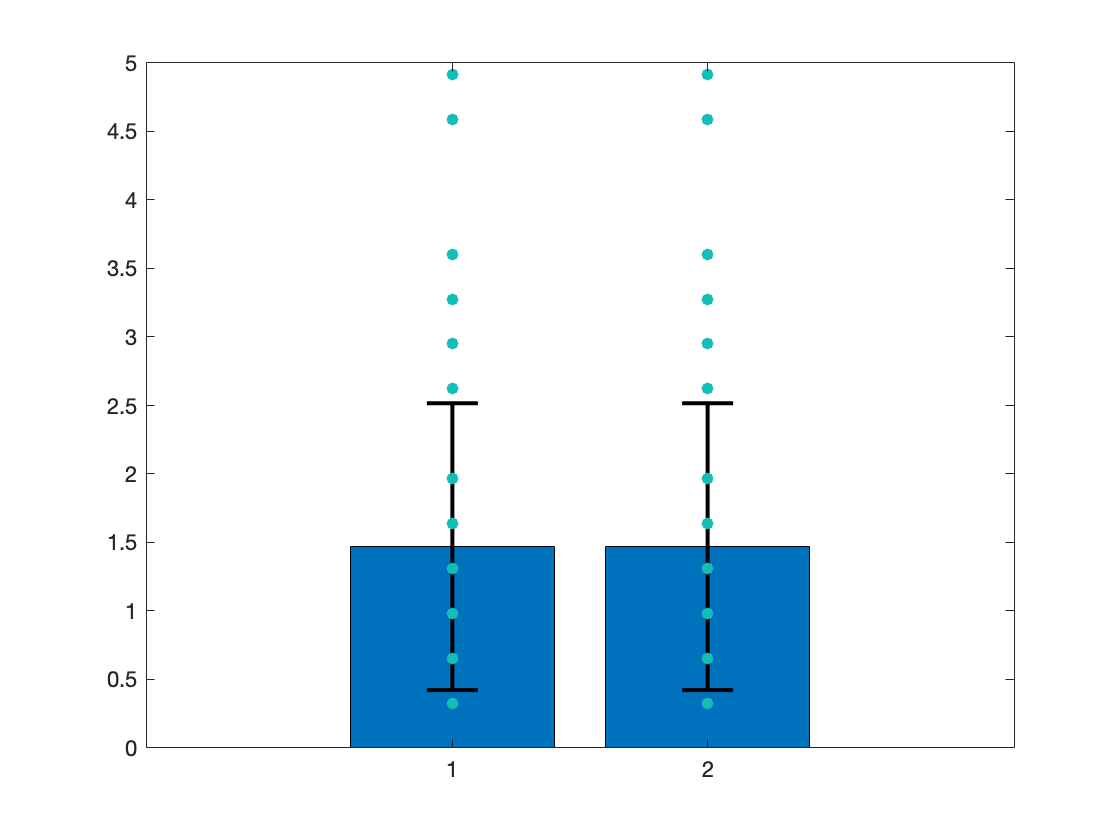

figure
la.drawFWHmHistByMonth(1) %channel 1으로 지정

## Figure 2.p.

phase-space

ㅇㅇㅇ

## Figure 2.q.

월별 cluster 개수 비교

월별 mean spike by clusters

월별 colored raster plot

## Figure 4.b.

                             %organoid, channel, month     
o1_ch1_m1 = channel("rawData.csv", 1, 1, 1);
o1_ch2_m1 = channel("rawData.csv", 1, 2, 1);
o1_ch1_m2 = channel("rawData.csv", 1, 1, 2);
o1_ch2_m2 = channel("rawData.csv", 1, 2, 2);

100-3000hz로 필터링

o1_ch1_m1.bandPass([100,3000])
o1_ch2_m1.bandPass([100,3000])
o1_ch1_m2.bandPass([100,3000])
o1_ch2_m2.bandPass([100,3000])

cluster 개수 3개, spike waveform 길이 +- 2ms로 spike detection 실행

o1_ch1_m1.detectSpikes(3,2,2)
o1_ch2_m1.detectSpikes(3,2,2)
o1_ch1_m2.detectSpikes(3,2,2)
o1_ch2_m2.detectSpikes(3,2,2)

channel object별로 raw trace 그리기. ylim 옵션을 이용해 비교대상끼리 y축 스케일 통일.

figure
%month 1

%ch1
subplot(2,2,1)
p = plot(o1_ch1_m1.t, o1_ch1_m1.raw);
p.Color = 'red'
title('ch1, month 1')
ylim([-4,4]*1e-3);%ylim 조절

%ch2
subplot(2,2,3)
p_o1_ch2_m1 = o1_ch2_m1.drawRaw('blue');
title('ch2, month 1')
ylim([-4,4]*1e-3);%ylim 조절


%month 2
%ch1
subplot(2,2,2)
p_o1_ch1_m2 = o1_ch1_m2.drawRaw('red');
title('ch1, month 2')
ylim([-5,5]*1e-3);%ylim 조절

%ch2
subplot(2,2,4)
p_o1_ch2_m2 = o1_ch2_m2.drawRaw('blue');
title('ch2, month 2')
ylim([-5,5]*1e-3);%ylim 조절

channel object별로 mean spike 그리기.

figure
subplot(2,1,1)
o1_ch1_m2.drawMeanSpike('red')
title('ch1, month2')
subplot(2,1,2)
o1_ch2_m2.drawMeanSpike('blue')
title('ch2, month2')

## Figure 4.c.

spectrogram(signal processing toolbox 필요)

x축 0s = 데이터 시작 시간(이 데이터에서는 약 30s)

figure
subplot(2,1,1)
spectrogram(o1_ch1_m2.raw, [], [], [], o1_ch1_m2.sf, 'yaxis')
title('ch1, month2, raw signal')

subplot(2,1,2)
spectrogram(o1_ch1_m2.filtered, [], [], [], o1_ch1_m2.sf, 'yaxis')
title('ch1, month2, filtered signal')

## Figure 4.d

power spectrums(signal processing toolbox 필요)

논문에서는 여러 month의 raw data를 비교하지만, 이 예제에서는 데이터 파일이 하나밖에 없으므로 플롯에서 구분이 되도록 month2에서는 filtered data를 사용

figure

xTable = timetable(seconds(o1_ch1_m1.t), o1_ch1_m1.raw); %raw data
[pxx,f] = pspectrum(xTable);
month1 = plot(f,pow2db(pxx));
month1.Color = 'red'

hold on

xTable = timetable(seconds(o1_ch1_m2.t), o1_ch1_m2.filtered); %filtered data
[pxx,f] = pspectrum(xTable);
month2 = plot(f,pow2db(pxx));
month2.Color = 'blue'

grid on

legend('month1', 'month2')
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Default Frequency Resolution')

## Figure 4.f.

phase-space analysis

원 논문에서는 sampling frequency가 30000으로 높아서, spike +- 2ms가 121개의 timestamp로 구성되므로(앞으로 60, 뒤로 60) trajectory의 모양이 복잡함(121 steps)

본 예제에서는 sampling frequency가 약 3000으로 낮아서, spike +- 2ms가 15개의 timestamp로 구성되므로(앞으로 7, 뒤로 7. 반올림 때문) trajectory의 모양이 단순함(15 steps)

figure
o1_ch1_m1.drawPhaseSpace('red')
hold on
o1_ch1_m2.drawPhaseSpace('blue')
hold off
legend('month1', 'month2')

o1_ch1_m1